%1)Load the audio/image
% The loaded audio has analog values that need to be restricted to a range
% for proper encoding
% The image consists of RGB channels with values in 0-255 
path="cat.mp4";
%read video
vidObj = VideoReader(path);

Error using VideoReader/init (line 601)
The filename specified was not found in the MATLAB path.

Error in VideoReader (line 171)
            obj.init(fileName);

% t=1.0/vidObj.FrameRate:1.0/vidObj.FrameRate:vidObj.Duration;
% t=[1]
t=1.0/vidObj.FrameRate:1:vidObj.Duration;

eof=false;

%write video
v = VideoWriter('cats2.avi');
v.FrameRate = vidObj.FrameRate;
open(v);

%%
% CRC is called cyclic redundancy check. It is used for checking if the
% transmission was accurate or erroneous.
% For 4-byte (32 bit) CRC calculation, use CRC32 algorithm.

% 2.1) Use comm.CRCGenerator with a 32 degree polynomial (Check Docs!)
% Generate a CRC generator object and pass it to the function
% This object is necessary because CRC values are not unique.

% Use this for th polynomial:
% 'z^32 + z^26 + z^23 + z^22 + z^16 + z^12 + z^11 + z^10 + z^8 + z^7 + z^5 + z^4 + z^2 + z + 1'

poly='z^32 + z^26 + z^23 + z^22 + z^16 + z^12 + z^11 + z^10 + z^8 + z^7 + z^5 + z^4 + z^2 + z + 1';
crcgenerator=comm.CRCGenerator(poly);
% 2.2) After generating a CRCGenerator above, create a CRCDetector Object for
% error detection here.
crcdetector=comm.CRCDetector(poly);


%3) modulation
%Declare modulation/demodulation schemes to convert the data to signal
%Hint:comm.BPSKModulator
%%%%%%%%%%%bpsk%%%%%%%%%%%%%%%%%%%%%%%%%%%%
M = 2;                 % Modulation alphabet
k = log2(M);           % Bits/symbol
bpskModulator = comm.BPSKModulator;
errorRate = comm.ErrorRate;
bpskDemodulator = comm.BPSKDemodulator;
%%%%%%%%%%qpsk%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% M = 4;                 % Modulation alphabet
% k = log2(M);           % Bits/symbol
% qpskMod = comm.QPSKModulator('BitInput',true);
% qpskDemod = comm.QPSKDemodulator('BitInput',true);


%4) ofdm
%Declare the OFDM modulator and demodulator with the following parameters
%Hint:comm.OFDMModulator
numSC = 52;           % Number of OFDM subcarriers
cpLen = 32;            % OFDM cyclic prefix length
maxBitErrors = 100;    % Maximum number of bit errors
maxNumBits = 1e7;      % Maximum number of bits transmitted
ofdmMod = comm.OFDMModulator('FFTLength',numSC,'CyclicPrefixLength',cpLen);
ofdmDemod = comm.OFDMDemodulator('FFTLength',numSC,'CyclicPrefixLength',cpLen);
ofdmDims = info(ofdmMod)

ofdmDims = struct with fields:
    DataInputSize: [41 1]
       OutputSize: [84 1]


numDC = ofdmDims.DataInputSize(1)

numDC = 41

frameSize = [k*numDC 1];

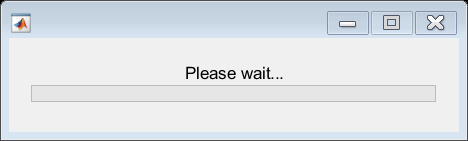

%5) channel
%The channel has to be modeled as awgn with SNR 10dB
channel = comm.AWGNChannel('NoiseMethod','Variance', ...
    'VarianceSource','Input port');
EbNoVec = (0:10)';
snrVec = EbNoVec + 10*log10(k) + 10*log10(numDC/numSC);

%result
berVec = zeros(length(EbNoVec),3);
errorStats = zeros(1,3);

%progess
f = waitbar(0,'Please wait...');


% for m = 1:length(EbNoVec)
    m=1;
    snr = snrVec(m);
    for time = t
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Input%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %get video frame from file
        vidObj.CurrentTime=time;
        frame = readFrame(vidObj);
        %imshow(frame);
        frame=imresize(frame,[64 64]);
        % imshow(frame);
        size(frame);
        image= frame;
        % while(hasFrame(vidObj))
        % %    vidObj.CurrentTime=time
        %    frame = readFrame(vidObj);
        %    imresize(frame,[64 64])
        %    imshow(frame);
        %    title(sprintf('Current Time = %.3f sec', vidObj.CurrentTime));
        %    pause(1/vidObj.FrameRate);

        %serialize image data
        data=image(:);
        %convert data to bits
        b = de2bi(data,'left-msb',8)';%converting to binary(column vector) where eight bits mean a number
        bits=b(:);
        txData=double(bits);
        %packetization 
        % Encapsulation : The process of encapsulating the data received from upper layers of the network(also called as payload) in a network layer packet at the source
        mac_phy_frame_buff= encapsulating_packetization(txData,frameSize,crcgenerator);
%         rx_frame_buff=[];
%         [Q,R]=quorem(sym(size(txData,1)),sym(frameSize(1)));
%         rows=frameSize(1);
%         cols=double(Q)+1;
%         mac_phy_frame_buff=zeros(rows,cols);
%         mac_phy_frame_buff(1:size(txData,1))=txData(:);
        for txData=mac_phy_frame_buff
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%modulation%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %3.1)Apply the defined modulation scheme
            %4.1)Apply OFDM modulation on BPSK/PSK/QAM modulated data
            modData = bpskModulator(txData); %Apply BPSK modulation
            txSig = ofdmMod(modData);% Apply OFDM modulation

            %figure(1);
            %scatterplot(modData);
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%channel%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %5)Apply the channel channel characteristics on modulated signal
            %rxSig = awgn(modData,10);                % Pass through AWGN
            powerDB = 10*log10(var(txSig));               % Calculate Tx signal power
            noiseVar = 10.^(0.1*(powerDB-snr));           % Calculate the noise variance
            rxSig = channel(txSig,noiseVar);              % Pass the signal through a noisy channel
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%demodulation%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %4.2)Apply OFDM demodulation on received signal
            %3.2)Apply the defined demodulation scheme
            bpskRx = ofdmDemod(rxSig);                    % Apply OFDM demodulation
            rxData = bpskDemodulator(bpskRx);       % Demodulate
            %figure(2);
            %scatterplot(rxData);
            errorStats = errorRate(txData,rxData); % Collect error stats
            %fprintf('Error rate = %f\nNumber of errors = %d\n',errorStats(1), errorStats(2));
            rx_frame_buff=[rx_frame_buff rxData];
        end
        bits = decapsulating_packetization (rx_frame_buff,size(bits,1),crcdetector)
%         isequal(bits,rx_frame_buff(1:size(bits,1)));
%         bits=rx_frame_buff(1:size(bits,1));
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%transmission%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        %convert bits to group of 8
        bits=reshape(bits,8,[])';

        %converting bits to image value
        data = bi2de(bits,'left-msb')';%converting to binary(column vector) where eight bits mean a number

        %making the image array
        image=reshape(image,64,64,3);

        % time=1:0.1:10;
        % path="cat.mp4";
        % vidObj = VideoReader(path);

        if eof
            close(v);
        else
        % for i = time
        % vidObj.CurrentTime=i
        % frame = readFrame(vidObj);
        %imshow(frame);
        % frame=imresize(frame,[64 64]);
        % imshow(frame);
        % size(frame);
            frame= im2frame(image);
            writeVideo(v,frame);
        end
        
        % 9) If correct message received, send ACK else NACK from the receiver.
        % ack is the 7 bit sequence 000 0110
        % nack is the 7 bit sequence 001 0101
        % use modulate.m
%         ack=[0 0 0 0 1 1 0];
%         nack=[0 0 1 0 1 0 1];
% 
%         if(err==0)
%             mod_cnfrm= modulate([0 ack], ta, ns, fc);
%         else
%             mod_cnfrm= modulate([0 nack], ta, ns, fc);
%         end
%         % 10) sender receives the acknowledgement.
%         % use demodulate.m
%         %all([1,1,1,1,1])
%         received_cnfrm = demodulate(mod_cnfrm, ta, ns, fc)
%         if(all(received_cnfrm(2:8)==ack))
%             fprintf ( "Success");    
%         elseif(all(received_cnfrm(2:8)==nack))
%             fprintf ( "Fail");    
%         end
         waitbar(time/vidObj.Duration,f,sprintf('Processing %f / %f , Error rate : %f ',time,vidObj.Duration,errorStats(1)));
    end

Error using waitbar (line 100)
The second argument must be a message character vector or a handle to an existing waitbar.

    berVec(m,:) = errorStats;                         % Save BER data
    reset(errorRate)        % Reset the error rate calculator
% end


% berTheory = berawgn(EbNoVec,'psk',M,'nondiff');
% 
% figure
% semilogy(EbNoVec,berVec(:,1),'*')
% hold on
% semilogy(EbNoVec,berTheory)
% legend('Simulation','Theory','Location','Best')
% xlabel('Eb/No (dB)')
% ylabel('Bit Error Rate')
% grid on
% hold off
close(v);
close(f);

Error using close
Invalid figure handle.

Undefined function or variable 'time'.